# Revision del dataset banknote paso a paso

Mismo esquema que con Iris: cada seccion deja una tabla en el workspace y R3 entrena el perceptron y el Adaline sobre cada una.

clear; close all; clc

## Paso 0: cargar y mirar el dato crudo

1372 billetes. A cada uno le tomaron una foto, le aplicaron una transformada wavelet y de ahi sacaron cuatro numeros que describen la textura. La clase dice si el billete es autentico (0) o falso (1).

datos = load('data_banknote_authentication.txt');
T = array2table(datos(:, 1:4), 'VariableNames', {'varianza', 'asimetria', 'curtosis', 'entropia'});
T.clase = categorical(datos(:, 5), [0 1], {'autentico', 'falso'});
vars = T.Properties.VariableNames(1:4);

T0_crudo = T;
disp(head(T0_crudo))

    varianza    asimetria    curtosis    entropia      clase  
    ________    _________    ________    ________    _________

     3.6216       8.6661     -2.8073     -0.44699    autentico
     4.5459       8.1674     -2.4586      -1.4621    autentico
      3.866      -2.6383      1.9242      0.10645    autentico
     3.4566       9.5228     -4.0112      -3.5944    autentico
    0.32924      -4.4552      4.5718      -0.9888    autentico
     4.3684       9.6718     -3.9606      -3.1625    autentico
     3.5912       3.0129     0.72888      0.56421    autentico
     2.0922        -6.81      8.4636     -0.60216    autentico



summary(T0_crudo)


T0_crudo: 1372×5 table

Variables:

    varianza: double
    asimetria: double
    curtosis: double
    entropia: double
    clase: categorical (2 categories)

Statistics for applicable variables:

                 NumMissing        Min           Median           Max           Mean           Std    

    varianza         0            -7.0421         0.4962         6.8248         0.4337        2.8428  
    asimetria        0           -13.7731         2.3197        12.9516         1.9224        5.8690  
    curtosis         0            -5.2861         0.6166        17.9274         1.3976        4.3100  
    entropia         0            -8.5482        -0.5867         2.4495        -1.1917        2.1010  
    clase            0                                                                                



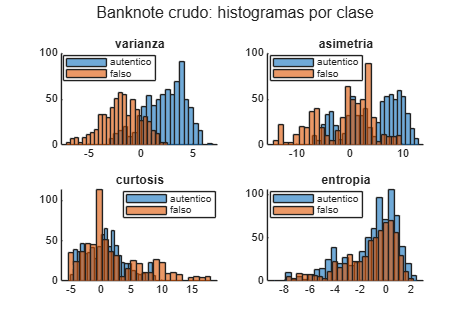


% distribucion de cada variable por clase
figure('Position', [100 100 900 600]);
for k = 1:4
    subplot(2, 2, k); hold on
    for c = categories(T.clase)'
        histogram(T.(vars{k})(T.clase == c{1}), 25, 'DisplayName', c{1});
    end
    title(vars{k}); legend('Location', 'best');
end
sgtitle('Banknote crudo: histogramas por clase');
guardar_fig('rev_banknote_histogramas');

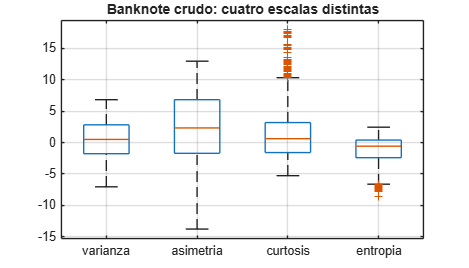


% boxplot: las cuatro estan en escalas distintas, la curtosis llega a 18
% y la entropia no pasa de 2.5
figure('Position', [100 100 700 400]);
boxplot(T{:, vars}, 'Labels', vars); grid on
title('Banknote crudo: cuatro escalas distintas');
guardar_fig('rev_banknote_boxplot_crudo');

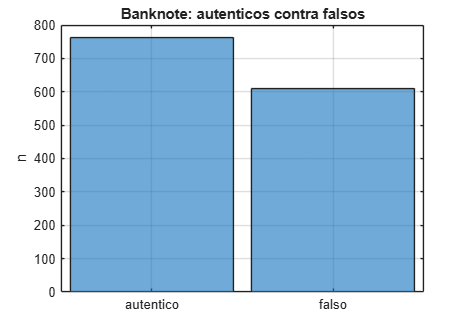


% balance de la clase
figure('Position', [100 100 500 350]);
histogram(T.clase); ylabel('n'); title('Banknote: autenticos contra falsos'); grid on
guardar_fig('rev_banknote_balance');

disp(table(categories(T.clase), countcats(T.clase), 'VariableNames', {'clase', 'n'}))

        clase         n 
    _____________    ___

    {'autentico'}    762
    {'falso'    }    610



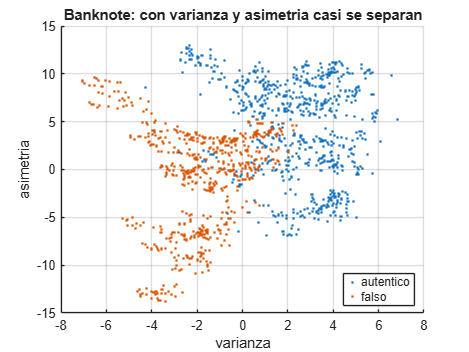


% dispersion de las dos mas informativas
figure('Position', [100 100 600 450]);
gscatter(T.varianza, T.asimetria, T.clase);
xlabel('varianza'); ylabel('asimetria'); grid on
title('Banknote: con varianza y asimetria casi se separan');
guardar_fig('rev_banknote_dispersion');


% Lo que se ve: 762 autenticos y 610 falsos, un desbalance suave. Las
% escalas son distintas entre variables, asi que estandarizar o
% normalizar deberia importar. La varianza sola ya separa bastante.

## Paso 1: corregir outliers

Regla del 1.5*IQR recortando al borde.

T1_outliers = T0_crudo;
for k = 1:4
    x = T1_outliers.(vars{k});
    q = quantile(x, [0.25 0.75]);
    li = q(1) - 1.5*(q(2)-q(1));
    ls = q(2) + 1.5*(q(2)-q(1));
    fprintf('%-10s: %d valores fuera de [%.2f, %.2f]\n', vars{k}, sum(x<li | x>ls), li, ls);
    x(x < li) = li;  x(x > ls) = ls;
    T1_outliers.(vars{k}) = x;
end

varianza  : 0 valores fuera de [-8.67, 9.72]
asimetria : 0 valores fuera de [-14.50, 19.60]
curtosis  : 57 valores fuera de [-8.75, 10.34]
entropia  : 33 valores fuera de [-6.63, 4.61]


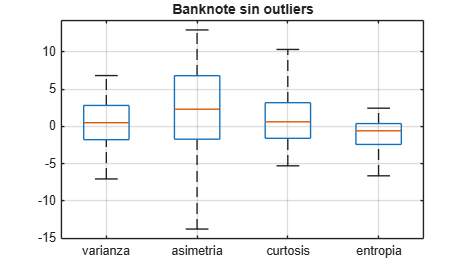


figure('Position', [100 100 700 400]);
boxplot(T1_outliers{:, vars}, 'Labels', vars); grid on
title('Banknote sin outliers');
guardar_fig('rev_banknote_boxplot_outliers');

## Paso 2: balancear las clases

Se toman al azar 610 autenticos para igualar a los 610 falsos.

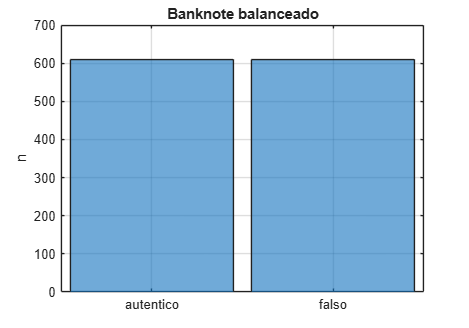

rng(1)
falsos = T1_outliers(T1_outliers.clase == 'falso', :);
autenticos = T1_outliers(T1_outliers.clase == 'autentico', :);
autenticos = autenticos(randperm(height(autenticos), height(falsos)), :);
T2_balanceado = [autenticos; falsos];

figure('Position', [100 100 500 350]);
histogram(T2_balanceado.clase); ylabel('n'); title('Banknote balanceado'); grid on
guardar_fig('rev_banknote_balance_despues');

fprintf('Antes: %d filas. Despues: %d filas (%d de cada clase).\n', ...
    height(T1_outliers), height(T2_balanceado), height(falsos));

Antes: 1372 filas. Despues: 1220 filas (610 de cada clase).


## Paso 3: estandarizar (media 0, desviacion 1)

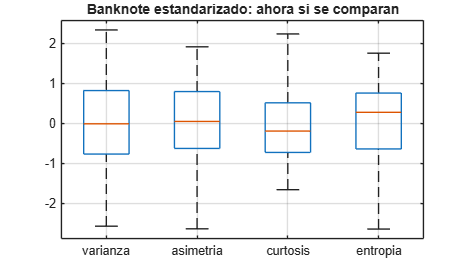

T3_estandarizado = T2_balanceado;
for k = 1:4
    T3_estandarizado.(vars{k}) = zscore(T2_balanceado.(vars{k}));
end
figure('Position', [100 100 700 400]);
boxplot(T3_estandarizado{:, vars}, 'Labels', vars); grid on
title('Banknote estandarizado: ahora si se comparan');
guardar_fig('rev_banknote_boxplot_estandarizado');

## Paso 4: normalizar (entre 0 y 1)

Parte del balanceado, no del estandarizado.

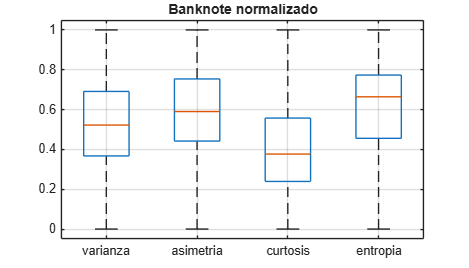

T4_normalizado = T2_balanceado;
for k = 1:4
    x = T2_balanceado.(vars{k});
    T4_normalizado.(vars{k}) = (x - min(x)) / (max(x) - min(x));
end
figure('Position', [100 100 700 400]);
boxplot(T4_normalizado{:, vars}, 'Labels', vars); grid on
title('Banknote normalizado');
guardar_fig('rev_banknote_boxplot_normalizado');

## Resumen

disp('Tablas listas, una por paso:')

Tablas listas, una por paso:


disp({'T0_crudo'; 'T1_outliers'; 'T2_balanceado'; 'T3_estandarizado'; 'T4_normalizado'})

    {'T0_crudo'        }
    {'T1_outliers'     }
    {'T2_balanceado'   }
    {'T3_estandarizado'}
    {'T4_normalizado'  }




% se guardan para que R3 las use con el perceptron y el Adaline
save('banknote_pasos.mat', 'T0_crudo', 'T1_outliers', 'T2_balanceado', 'T3_estandarizado', 'T4_normalizado');